
clear all; close all;

- Laden Sie das gespeicherte EKG (e23.mat). Stellen Sie es mit den Parametern TA=4 ms und Verstärkungsfaktor V=100 als reales EKG dar. Im Weiteren soll wegen der einfacheren Handhabung mit Indizes und nicht mit physikalischen Einheiten gearbeitet werden. Dies erleichtert die Analyse, denn die Einheiten können im Ergebnis hinzugefügtwerden.

Erzeugen Sie einen Ausgleichsvorgang aus zwei e-Funktionen, wobei die am Anfang aktive Abfallzeitkonstante 1 s und die ihr folgende Anstiegszeitkonstante 3 s betragen sollen. Addieren Sie diesen Ausgleichsvorgang zum EKG so, dass er bei t=4 s bzw.	Zeitindex 1001 beginnt. Stellen Sie den Zeitverlauf dar, er sollte dem Verlauf in	folgender Abbildung entsprechen: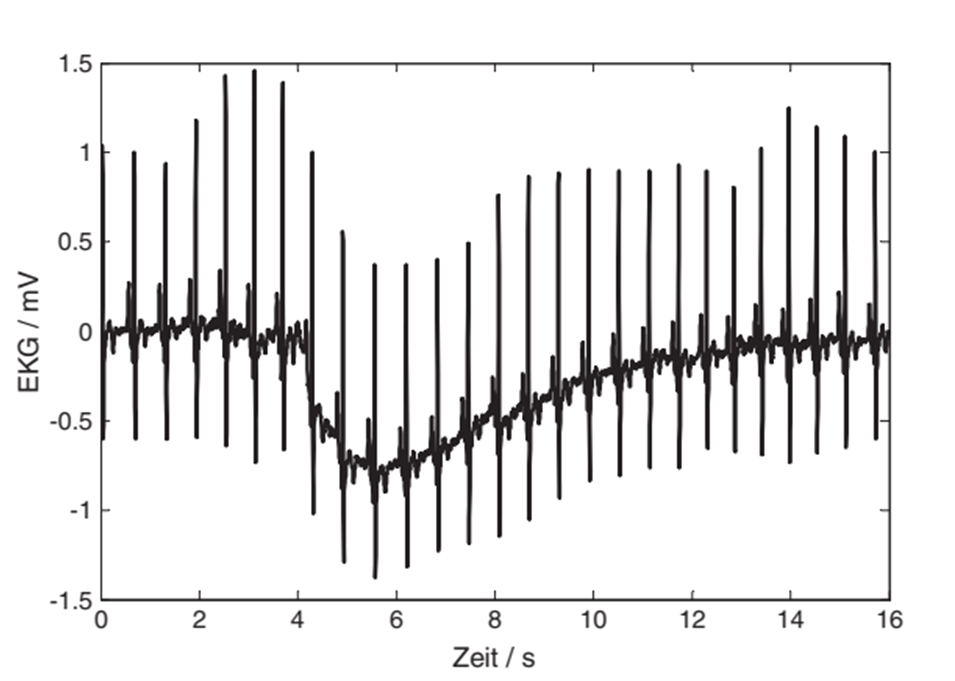

load e23            

% Ausgleichsvorgang berechnen, Amplitude in etwa gleich R-Zacke
t = 0:2999;
dt=4e-3;
aus = exp(-t/250)-exp(-t/750);
aus = aus(:);
aus = 200*aus;
t_aux=1:length(aus)

t_aux =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


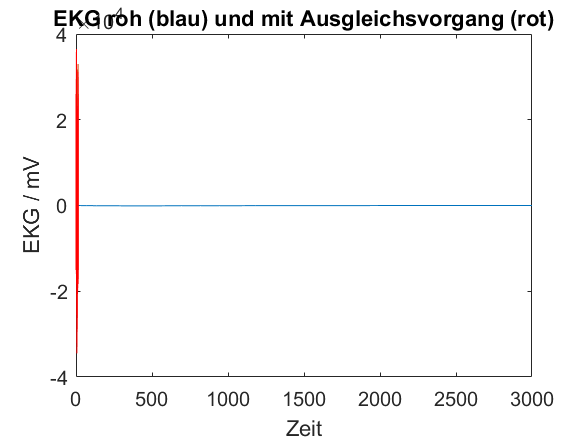

plot(t_aux,aus)

% Ausgleichsvorgang zum EKG an der Stelle t=4s addieren
ekgaus = e23;
aux=ekgaus;
ekgaus(1001:4000) = ekgaus(1001:4000)+aus;
tax = (0:3999)*dt; % Zeitachse zum Plotten
figure(1), hold on, plot(tax, e23/dt), 
plot(tax, ekgaus/dt,'r'), hold off
xlabel('Zeit'), ylabel('EKG / mV'), title('EKG roh (blau) und mit Ausgleichsvorgang (rot)')

legend('Original','Ausgleichsvorgang')
spec=fft(e23);
spec_aus=fft(ekgaus);
plot(abs(spec))
hold on
plot(abs(spec_aus))
hold off

xlim([0 100])
ylim([00 1e4])

 Berechnen Sie die Spektren des Original-EKG, des Ausgleichsvorgangs und des gestörten EKG und stellen diese dar. Entscheiden Sie an Hand der Spektren, an welcher Stelle die Grenzfrequenz eines Hochpasses liegen kann, mit dem der Ausgleichsvorgang unterdrückt werden soll. Beachten Sie dabei, dass die Grundwelle des EKG mit ihren Seitenbändern (die erste Harmonische der Herzrate mit benachbarten spektralen Spitzen der Atmung) nicht beeinträchtigt werden darf. In welchem	Bereich könnte die Grenzfrequenz liegen?

  Entwerfen Sie einen Hochpass mithilfe der Matlab-Pakete SPtool oder FDAtool als ein FIR und ein IIR-Filter. Vergleichen Sie die Wirkung der Hochpässe auf das Artefakt und auf die Signalform des EKG. Welches Filter verursacht die kürzeste Verzögerung? Welches Filter kann die Signalform des EKG eventuell verzerren? Welches	Filter mit welcher Grenzfrequenz wäre für diese Messaufgabe unter Berücksichtigungder Anforderungen an die Messkette besser geeignet?

% FIR-Hochpass
load fir_hp         % gespeicherter Entwurf eines FIR-Hochpasses
ekg_fir_hp = highpass(ekgaus,1.2,1/dt,"ImpulseResponse","auto"); % Signalfilterung
figure(2), plot(ekg_fir_hp,'r'), hold on, plot(ekgaus,'b'), hold off 
xlabel('Zeitindex'), ylabel('Pegelindex'), 
title('EKG mit Ausgleichsvorgang (blau) und nach FIR-Hochpassfilter (rot)')  % Vergleich der Verläufe vor und nach Filterung
legend('Original','FIR')
% IIR-Hochpass
load iir_hp         % gespeicherter Entwurf eines IIR-Hochpasses
%iir_hp=dsp.IIRFilter
ekg_iir_hp = filter(iir_hp.tf.num,iir_hp.tf.den,ekgaus); % Signalfilterung
figure(3), plot(ekg_iir_hp,'r'), %hold on, plot(ekgaus,'b'), hold off 
xlabel('Zeitindex'), ylabel('Pegelindex')
title('EKG mit Ausgleichsvorgang (blau) und nach IIR-Hochpassfilter (rot)') % Vergleich der Verläufe vor und nach Filterung
legend('IIR','Original')
% Betrachten Sie die ersten Sekunden der Aufnahme (axis([0 500 -150 150])). Wie unterscheiden sich die gefilterten Verläufe?

% Vergleich der Spektren des Originals, des Artefaktbehafteten und der gefilterten Signale
fax = (0:3999)*250/4000; % Frequenzachse
figure(4)
plot(fax, abs(fft(e23))/4000), , hold, axis([0 5 0 2])
plot(fax, abs(fft(ekgaus))/4000,'k')
plot(fax, abs(fft(ekg_fir_hp))/4000,'r')
plot(fax, abs(fft(ekg_iir_hp))/4000,'c')
xlabel('Frequenz / Hz'), ylabel('spektraler Pegel'), title('Spektren: Original (blau), mit Ausgleichsvorgang (schwarz), FIR (rot), IIR (cyan)')
legend('Original','Ausgleichsvorgang','FIR','IIR')